clc; clear all; close all; 

## Data Summary and Visualisation

### Working Directory

% Set working directory to the current directory 
addpath('src');
addpath("data/raw/")

### Import Data

Loading Sheet 1:

No0x2E2WT


Loading Sheet 2:

No0x2E3


Loading Sheet 3:

No0x2E14WT


Loading Sheet 4:

No0x2E39WT


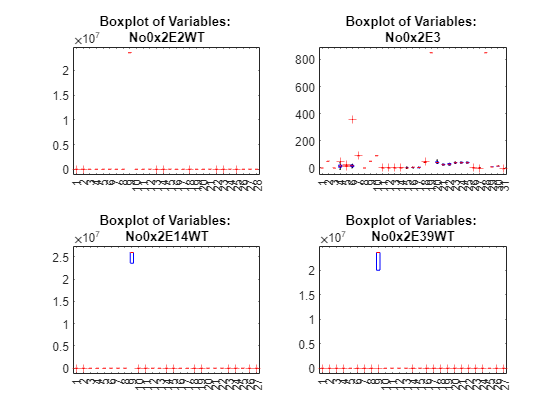

%Suppress warnings
warning('off');

% Define the Excel file name
excelFileName = 'data.xlsx';

% Get the sheet names from the Excel file
[~, sheetNames] = xlsfinfo(excelFileName);

% Loop through each sheet, read it into a table 
for i = 1:length(sheetNames)
    fprintf("Loading Sheet %d:", i)
    sheetName = sheetNames{i};
    % Generate a valid variable name in MATLAB
    tableName = genvarname(sheetName); 
    tableData = readtable(excelFileName, 'Sheet', sheetName, 'ReadVariableNames', true);
    % Save the table with the sheet name as the table name
    assignin('base', tableName, tableData);
    %Display the table name
    disp(tableName)

    % % Save the summary stats in an excel file
    currentDir = pwd;
    mainFolder = 'data';
    subFolder = 'processed';
    destinationFolder = fullfile(currentDir, mainFolder, subFolder);

    % Create the folder if it does not exist
    if ~exist(fullfile(currentDir, destinationFolder), 'dir')
        mkdir(fullfile(destinationFolder));
    end

    % Define the output file name
    outputFileName = fullfile(destinationFolder, 'summary.xls');
    
    % Write the table to Excel
    writetable(PCALib.summarystats(eval(tableName)), outputFileName, 'Sheet', i);

    
    % Visualize the data in the table using boxplots
    folderName = 'images';

    % Create a folder named "images" if it does not exist
    if ~exist(fullfile(currentDir, folderName), 'dir')
        mkdir(fullfile(folderName));
    end
    subplot(2, 2, i)
    boxplot(table2array(eval(tableName)))
    title([sprintf('Boxplot of Variables: \n'), tableName])

    if i==length(sheetNames)
        saveas(gcf, fullfile('images', 'unscaledBoxplot.png'));
        % close(gcf); 
    end
end

## Data Pretreatment

### Discard the dataset for `WT3`

clear No0x2E3;

### Drop one of the columns in the dataset for `WT2`

No0x2E2WT = removevars(No0x2E2WT, "x28");

% rowsToRemove = [1423, 1022, 1372];
% No0x2E2WT(rowsToRemove, :) = [];

### Drop two columns in the three datasets

dataTables = {'No0x2E2WT', 'No0x2E14WT', 'No0x2E39WT'};
% These variables are constant in the healthy turbine data
varToRemove = {'x12', 'x15'};
for i = 1:numel(dataTables)
    tableName = dataTables{i};
    for j = 1:numel(varToRemove)
        variableName = varToRemove{j};
        eval([tableName, ' = removevars(', tableName, ', "', variableName, '");']);
    end
end

### Drop the observation with the missing value

No0x2E14WT = rmmissing(No0x2E14WT);

### Data centering and scaling

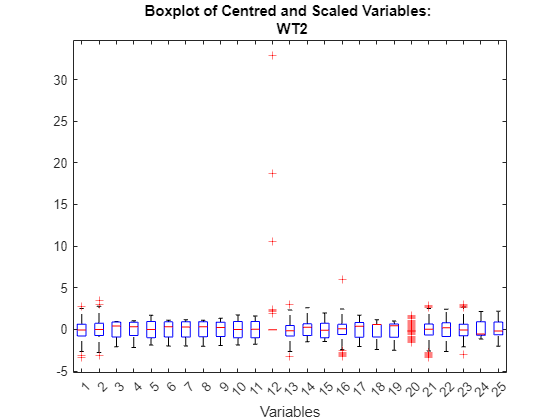

% % Center and scale the data for the healthy turbine
model.varNames = No0x2E2WT.Properties.VariableNames;

[model.No0x2E2WT, model.mu, model.sigma] = zscore(table2array(No0x2E2WT));

% Create a boxplot for the centered and scaled healthy turbine
figure;
boxplot(model.No0x2E2WT);
title(sprintf('Boxplot of Centred and Scaled Variables: \n WT2'));
xlabel('Variables');

saveas(gcf, fullfile('images', 'No0x2E2Boxplot.png'));

model.No0x2E14WT

model = struct with fields:
      varNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x13'  'x14'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'  'x22'  'x23'  'x24'  'x25'  'x26'  'x27'}
     No0x2E2WT: [1570×25 double]
            mu: [-0.0074 -0.0116 26.3116 29.2803 315.3096 41.0436 40.9062 41.0798 2.3575e+07 320.6220 1.3203e+03 0.0110 -0.7541 223.6841 9.0433 685.0910 50.0023 17.6232 22.9118 10.7356 5.1643 5.4798 16.9228 53.2114 59.8223]
         sigma: [0.0455 0.0739 1.4622 1.6317 117.1357 2.2889 2.2389 2.2330 397.9615 117.0907 146.6609 0.0144 1.5969 15.4066 1.4409 2.1488 0.0454 0.3024 0.2864 0.2197 4.6742 0.7837 2.5627 3.1453 1.9001]
    No0x2E14WT: [685×25 double]


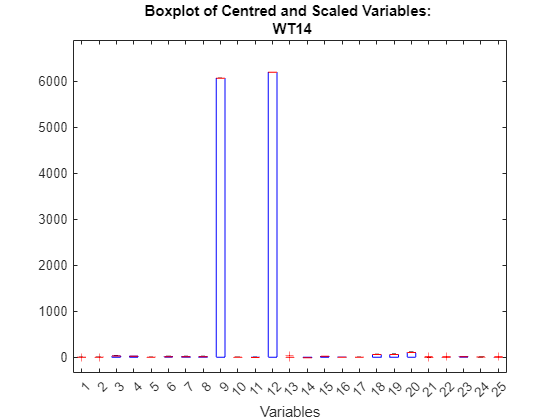

model.No0x2E39WT

model = struct with fields:
      varNames: {'x1'  'x2'  'x3'  'x4'  'x5'  'x6'  'x7'  'x8'  'x9'  'x10'  'x11'  'x13'  'x14'  'x16'  'x17'  'x18'  'x19'  'x20'  'x21'  'x22'  'x23'  'x24'  'x25'  'x26'  'x27'}
     No0x2E2WT: [1570×25 double]
            mu: [-0.0074 -0.0116 26.3116 29.2803 315.3096 41.0436 40.9062 41.0798 2.3575e+07 320.6220 1.3203e+03 0.0110 -0.7541 223.6841 9.0433 685.0910 50.0023 17.6232 22.9118 10.7356 5.1643 5.4798 16.9228 53.2114 59.8223]
         sigma: [0.0455 0.0739 1.4622 1.6317 117.1357 2.2889 2.2389 2.2330 397.9615 117.0907 146.6609 0.0144 1.5969 15.4066 1.4409 2.1488 0.0454 0.3024 0.2864 0.2197 4.6742 0.7837 2.5627 3.1453 1.9001]
    No0x2E14WT: [685×25 double]
    No0x2E39WT: [1405×25 double]


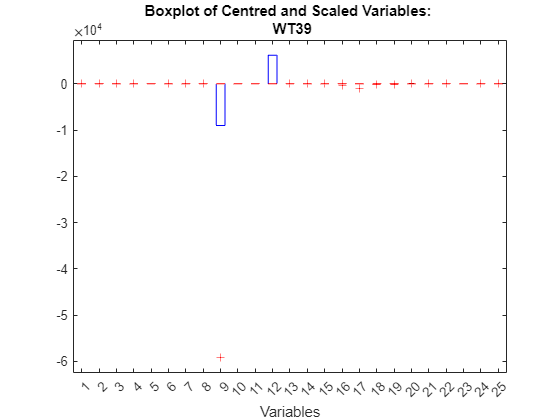


% %Apply the healthy turbine center and standard deviation to the faulty turbines
% Define the turbine numbers 
turbineNumbers = [14, 39];

% Create a loop to process each turbine
for i = 1:length(turbineNumbers)
    turbineNumber = turbineNumbers(i);
    
    % Access the corresponding windTurbine table
    windTurbine = evalin('base', sprintf('No0x2E%dWT', turbineNumber));
    
    % Normalize the data for the current turbine using the healthy turbine mean and standard deviation 
    fprintf(['model.' 'No0x2E' num2str(turbineNumber) 'WT'])
    model.(['No0x2E' num2str(turbineNumber) 'WT']) = normalize(table2array(windTurbine), 'Center', model.mu, 'Scale', model.sigma) 
    
    
    % Create a boxplot for the current turbine
    figure;
    boxplot(model.(['No0x2E' num2str(turbineNumber) 'WT']));
    title([sprintf('Boxplot of Centred and Scaled Variables: \n WT'), num2str(turbineNumber)]);
    xlabel('Variables');

    saveas(gcf, fullfile('images', ['No0x2E' num2str(turbineNumber) 'Boxplot.png']));
    % close(gcf);
end

## Model Calibration

### Selection of Optimal Number of Principal Components 

#### **Cumulative Explained Variance Plot**

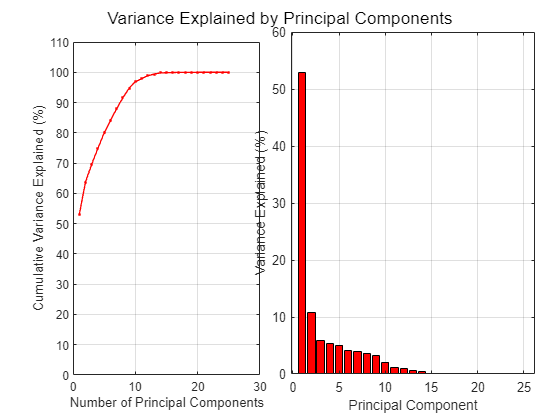

[model.P, model.T, model.latent, model.tsq, model.explained] = pca(model.No0x2E2WT, 'Centered', false);
model.explVar = 100 * cumsum(model.latent)/ sum(model.latent);

figure; 
subplot(1, 2, 1);
plot(1:length(model.explVar), model.explVar, 'r.-', 'LineWidth', 1); 
ylim([0 110]);
xlabel("Number of Principal Components");
ylabel("Cumulative Variance Explained (%)");
% title("Cumulative PC Contribution");
grid on;
subplot(1, 2, 2);
bar(model.explained, 'r');
xlabel("Principal Component");
ylabel("Variance Explained (%)");
% title("Individual PC Contribution");
grid on;
sgtitle("Variance Explained by Principal Components");
% Adjust subplot positions for better visualization
pos = get(gca, 'Position');
pos(1) = pos(1) - 0.05; 
pos(3) = pos(3) + 0.1;
set(gca, 'Position', pos);
saveas(gcf, fullfile('images', 'VarianceExplained.png'));

#### **Leave-One-Out Cross Validation **

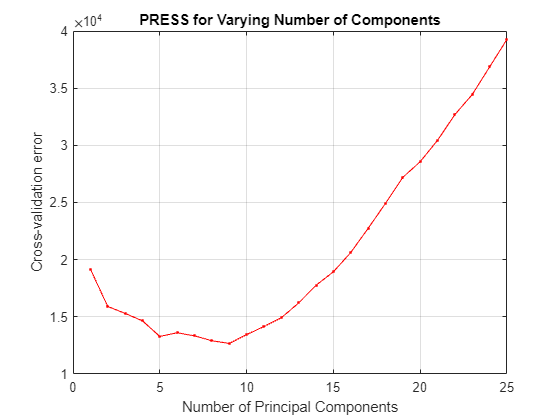

PCALib.pcaloocv(model.No0x2E2WT)

#### Control Charts

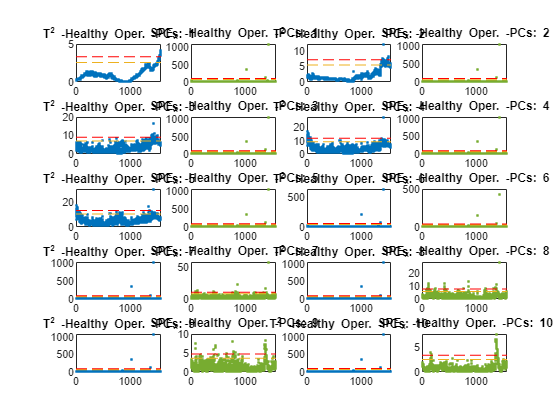

% Control Charts
[model.row, model.col]    =  size(model.No0x2E2WT);
figure;
ii = 1;
for i = 1:10
    model.ncomp(i).T2 = PCALib.t2comp(model.No0x2E2WT, model.P, model.latent, i);
    model.ncomp(i).T2warning = mean(model.ncomp(i).T2) + 2 * std(model.ncomp(i).T2);
    model.ncomp(i).T2alarm = mean(model.ncomp(i).T2) + 3 * std(model.ncomp(i).T2);

    subplot(5,4,ii); ii = ii + 1;
    plot(1:model.row, model.ncomp(i).T2, '.', 'Color', '#0072BD');
    hold on  
    plot([1, model.row], [model.ncomp(i).T2warning, model.ncomp(i).T2warning], '--', 'Color', '#EDB120');
    plot([1, model.row], [model.ncomp(i).T2alarm, model.ncomp(i).T2alarm], 'r--');
    title("T^2 -Healthy Oper. -PCs: " + string(i));
    % legend(["Scores", "Warning", "Alarm"]);

    model.ncomp(i).SPEx = PCALib.qcomp(model.No0x2E2WT, model.P, i);
    model.ncomp(i).SPEwarning = mean(model.ncomp(i).SPEx) + 2 * std(model.ncomp(i).SPEx);
    model.ncomp(i).SPEalarm = mean(model.ncomp(i).SPEx) + 3 * std(model.ncomp(i).SPEx);
    
    subplot(5,4,ii); ii = ii + 1;
    plot(1:model.row, model.ncomp(i).SPEx, '.', 'Color', '#77AC30');
    hold on
    plot([1, model.row], [model.ncomp(i).SPEwarning, model.ncomp(i).SPEwarning], '--', 'Color', '#EDB120');
    plot([1, model.row], [model.ncomp(i).SPEalarm,   model.ncomp(i).SPEalarm], 'r--');
    title("SPE_x -Healthy Oper. -PCs: " + string(i));
    % legend(["Scores", "Warning", "Alarm"]);
end
saveas(gcf, fullfile('images', 'HealthyTurbineControlCharts.png'));

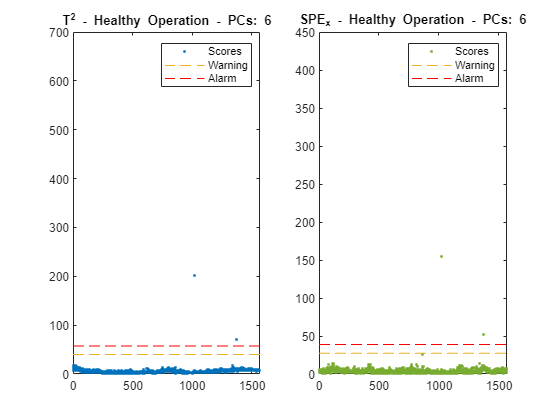


figure;

subplot(1,2,1)
plot(1:model.row, model.ncomp(6).T2, '.', 'Color', '#0072BD');
hold on  
plot([1, model.row], [model.ncomp(6).T2warning, model.ncomp(6).T2warning], '--', 'Color', '#EDB120');
plot([1, model.row], [model.ncomp(6).T2alarm, model.ncomp(6).T2alarm], 'r--');
title("T^2 - Healthy Operation - PCs: 6");
legend(["Scores", "Warning", "Alarm"]);

    
subplot(1,2,2); 
plot(1:model.row, model.ncomp(6).SPEx, '.', 'Color', '#77AC30');
hold on
plot([1, model.row], [model.ncomp(6).SPEwarning, model.ncomp(6).SPEwarning], '--', 'Color', '#EDB120');
plot([1, model.row], [model.ncomp(6).SPEalarm,   model.ncomp(6).SPEalarm], 'r--');
title("SPE_x - Healthy Operation - PCs: 6");
legend(["Scores", "Warning", "Alarm"]);
saveas(gcf, fullfile('images', 'HealthyTurbineControlCharts6PCs.png'));

### Optimal Model Calibration

% Specify the number of PCs to retain 
ncomp = 6;

## Fault Identification

limits = [model.ncomp(6).T2warning, model.ncomp(6).T2alarm, model.ncomp(6).SPEwarning, model.ncomp(6).SPEalarm];

### Control Charts for Healthy Turbine (2WT)

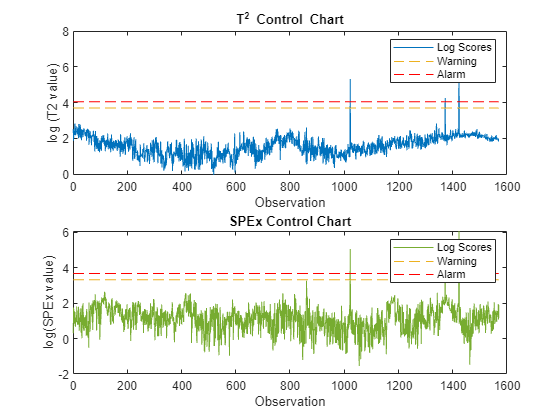

[model.T22WT, model.Q2WT, model.Class2WT] = PCALib.faultIdentification(model.No0x2E2WT, limits, model.P, model.latent, ncomp);

### Control Charts for Faulty Turbines

#### WT14

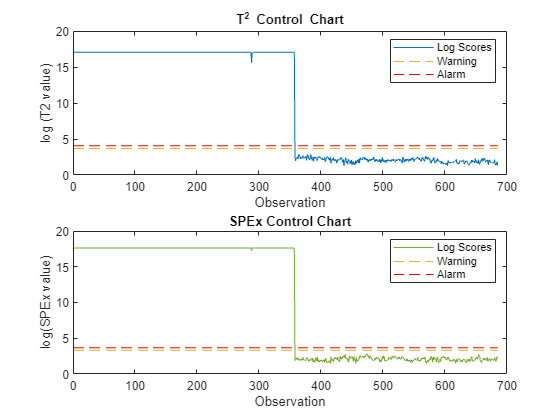

[model.T214WT, model.Q14WT, model.Class14WT] = PCALib.faultIdentification(model.No0x2E14WT, limits, model.P, model.latent, ncomp);
saveas(gcf, fullfile('images', 'WT14ControlChart.png'));

#### WT39

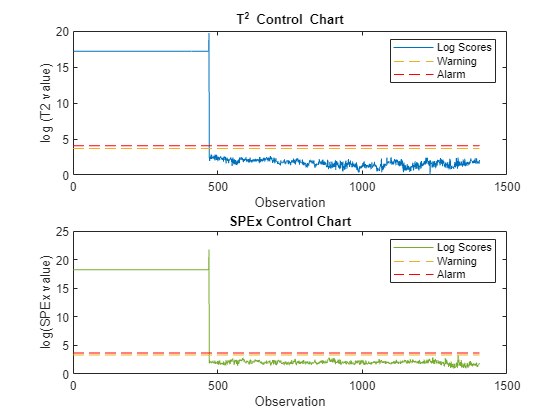

[model.T239WT, model.Q39WT, model.Class39WT] = PCALib.faultIdentification(model.No0x2E39WT, limits, model.P, model.latent, ncomp);
saveas(gcf, fullfile('images', 'WT39ControlChart.png'));

## Sensor Diagnostics

### WT14

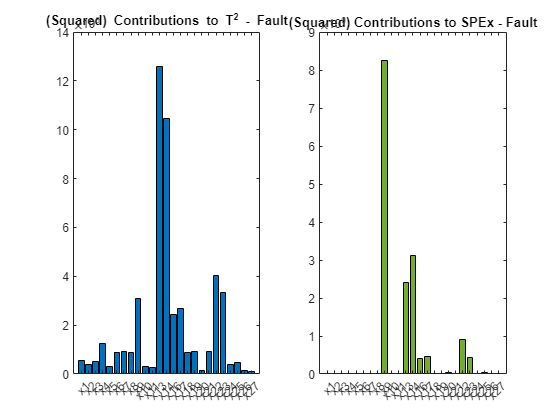

t2contr14 = PCALib.t2contr(model.No0x2E14WT(find(model.Class14WT == 'Out-of-Control'),:), model.P, model.latent, 6);
qcontr14 = PCALib.qcontr(model.No0x2E14WT(find(model.Class14WT == 'Out-of-Control'),:), model.P, 6);
figure;
subplot(1, 2, 1);
bar(t2contr14, 'FaceColor', '#0072BD');
xticklabels(model.varNames);
xticks(1:model.col);
title("(Squared) Contributions to T^2 - Fault");
xtickangle(45)
subplot(1, 2, 2);
bar(qcontr14, 'FaceColor', '#77AC30');
xticklabels(model.varNames);
xticks(1:model.col);
title("(Squared) Contributions to SPEx - Fault");
xtickangle(45)
saveas(gcf, fullfile('images', 'WT14ContributionPlot.png'));

#### WT39

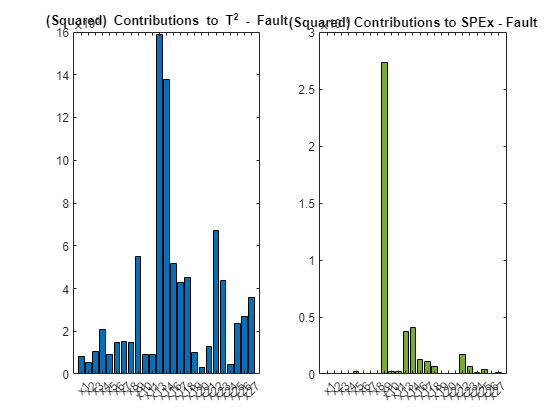

t2contr39 = PCALib.t2contr(model.No0x2E39WT(find(model.Class39WT == 'Out-of-Control'),:), model.P, model.latent, 6);
qcontr39 = PCALib.qcontr(model.No0x2E39WT(find(model.Class39WT == 'Out-of-Control'),:), model.P, 6);
figure;
subplot(1, 2, 1);
bar(t2contr39, 'FaceColor', '#0072BD');
xticklabels(model.varNames);
xticks(1:model.col);
title("(Squared) Contributions to T^2 - Fault");
xtickangle(45);
subplot(1, 2, 2);
bar(qcontr39, 'FaceColor', '#77AC30');
xticklabels(model.varNames);
xticks(1:model.col);
title("(Squared) Contributions to SPEx - Fault");
xtickangle(45);
saveas(gcf, fullfile('images', 'WT39ContributionPlot.png'));

ContributionTableT214 = table(model.varNames', t2contr14', 'VariableNames', {'VariableName', 'T^2 Value'});
ContributionTableT214Sorted = sortrows(ContributionTableT214, 'T^2 Value', 'descend');
disp(ContributionTableT214Sorted);

    VariableName    T^2 Value 
    ____________    __________

      {'x13'}       1.2597e+06
      {'x14'}       1.0448e+06
      {'x22'}       4.0256e+05
      {'x23'}       3.3275e+05
      {'x9' }       3.0806e+05
      {'x17'}       2.6623e+05
      {'x16'}       2.4228e+05
      {'x4' }       1.2354e+05
      {'x19'}            92293
      {'x7' }            91355
      {'x21'}            91013
      {'x18'}            89511
      {'x6' }            88747
      {'x8' }            87289
      {'x1' }            56096
      {'x3' }            50679
      {'x25'}            46681
      {'x24'}            38673
      {'x2' }            37608
      {'x10'}            29487
      {'x5' }            28739
      {'x11'}            28637
      {'x26'}            16294
      {'x20'}            15597
      {'x27'}           8245.5



ContributionTableSPEx14 = table(model.varNames', qcontr14', 'VariableNames', {'VariableName', 'SPEx Value'});
ContributionTableSPEx14Sorted = sortrows(ContributionTableSPEx14, 'SPEx Value', 'descend');
disp(ContributionTableSPEx14Sorted);

    VariableName    SPEx Value
    ____________    __________

      {'x9' }       8.2552e+09
      {'x14'}       3.1173e+09
      {'x13'}       2.3977e+09
      {'x22'}       9.1718e+08
      {'x17'}       4.6903e+08
      {'x23'}       4.3822e+08
      {'x16'}       4.0071e+08
      {'x20'}       4.3616e+07
      {'x25'}        4.229e+07
      {'x26'}        2.218e+07
      {'x19'}        1.998e+07
      {'x18'}       1.3221e+07
      {'x5' }       1.1466e+07
      {'x10'}       1.1169e+07
      {'x11'}       1.0938e+07
      {'x1' }       1.0612e+07
      {'x4' }        8.975e+06
      {'x24'}       6.0464e+06
      {'x27'}       5.8973e+06
      {'x3' }       4.1457e+06
      {'x2' }       2.7423e+06
      {'x7' }       6.2102e+05
      {'x6' }        3.844e+05
      {'x8' }       3.0617e+05
      {'x21'}            47702



ContributionTableT239 = table(model.varNames', t2contr39', 'VariableNames', {'VariableName', 'T^2 Value'});
ContributionTableT239Sorted = sortrows(ContributionTableT239, 'T^2 Value', 'descend');
disp(ContributionTableT239Sorted);

    VariableName    T^2 Value 
    ____________    __________

      {'x13'}       1.5873e+06
      {'x14'}       1.3755e+06
      {'x22'}       6.7269e+05
      {'x9' }       5.4843e+05
      {'x16'}       5.1629e+05
      {'x18'}       4.5345e+05
      {'x23'}       4.3623e+05
      {'x17'}       4.2874e+05
      {'x27'}       3.5903e+05
      {'x26'}       2.6729e+05
      {'x25'}       2.3414e+05
      {'x4' }       2.0946e+05
      {'x7' }       1.5263e+05
      {'x8' }       1.4915e+05
      {'x6' }       1.4788e+05
      {'x21'}       1.2802e+05
      {'x3' }       1.0635e+05
      {'x19'}            99803
      {'x5' }            93367
      {'x10'}            93201
      {'x11'}            89094
      {'x1' }            81642
      {'x2' }            54129
      {'x24'}            44260
      {'x20'}            32585



ContributionTableSPEx39 = table(model.varNames', qcontr39', 'VariableNames', {'VariableName', 'SPEx Value'});
ContributionTableSPEx39Sorted = sortrows(ContributionTableSPEx39, 'SPEx Value', 'descend');
disp(ContributionTableSPEx39Sorted);

    VariableName    SPEx Value
    ____________    __________

      {'x9' }       2.7305e+10
      {'x14'}       4.0631e+09
      {'x13'}       3.6971e+09
      {'x22'}       1.7454e+09
      {'x16'}       1.2936e+09
      {'x17'}       1.0982e+09
      {'x23'}       6.6056e+08
      {'x18'}       6.3265e+08
      {'x25'}        4.174e+08
      {'x5' }       1.8408e+08
      {'x10'}        1.837e+08
      {'x11'}       1.8298e+08
      {'x27'}       1.0293e+08
      {'x24'}       9.2746e+07
      {'x20'}       6.2671e+07
      {'x1' }       3.3864e+07
      {'x4' }       3.2394e+07
      {'x26'}         1.13e+07
      {'x19'}       5.4407e+06
      {'x21'}        2.707e+06
      {'x3' }       1.8385e+06
      {'x7' }       1.7237e+06
      {'x8' }       1.3292e+06
      {'x6' }       1.0239e+06
      {'x2' }        5.188e+05



### Univariate Evaluation

#### WT14

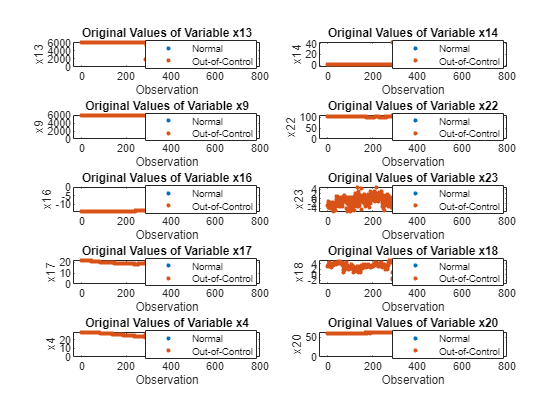

[r, c] = size(model.No0x2E14WT);
varNo = [12, 13, 9, 20, 14, 21, 15, 16, 4, 18];
figure;
for i= 1:length(varNo)
    subplot(5, 2, i);
    gscatter(1:r, model.No0x2E14WT(:,varNo(i)), model.Class14WT);
    xlabel('Observation');
    ylabel(model.varNames(varNo(i)));
    title('Original Values of Variable '+ string(model.varNames(varNo(i))));
end
saveas(gcf, fullfile('images', 'WT14OriginalValues.png'));

#### WT39

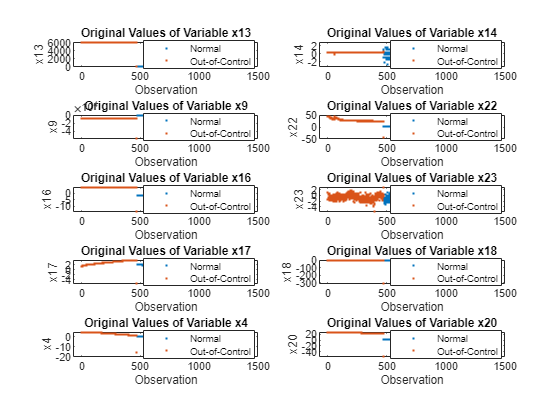

[rw, cl] = size(model.No0x2E39WT);
varNo = [12, 13, 9, 20, 14, 21, 15, 16, 4, 18];
figure;
for i= 1:length(varNo)
    subplot(5, 2, i);
    gscatter(1:rw, model.No0x2E39WT(:,varNo(i)), model.Class39WT);
    xlabel('Observation');
    ylabel(model.varNames(varNo(i)));
    title('Original Values of Variable '+ string(model.varNames(varNo(i))));
end
saveas(gcf, fullfile('images', 'WT39OriginalValues.png'));